# The Best Automatic Wordle Strategy

This script investigates an automated strategy for solving Wordle, using only target words and playing on "hard mode".

% Load words and associated data
load wordpairings.mat

% Make nice text versions of the score possibilities
scores = stringscore(0:242);
% Get probability distribution of letters (A-Z in word positions 1:5)
p = letterdistribution(testwords);
% Look up probabilities for each letter in the word list
probs = p(sub2ind([26,5],char(testwords)-64,repmat(1:5,numel(testwords),1)));

The algorithm is based on the idea of how a word correlates with all the possible target words, in terms of the distribution of responses from the 243 possible responses (3^5 combinations of grey/yellow/green).

Look at some example distributions

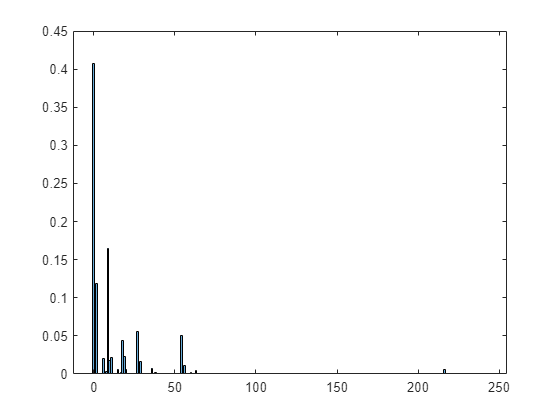

% Look at the distribution of score possibilities for two different word
% guesses - one bad, one good (probably)
idx = testwords == "QUEUE";
histogram(D(:,idx),"BinMethod","integers","Normalization","probability")

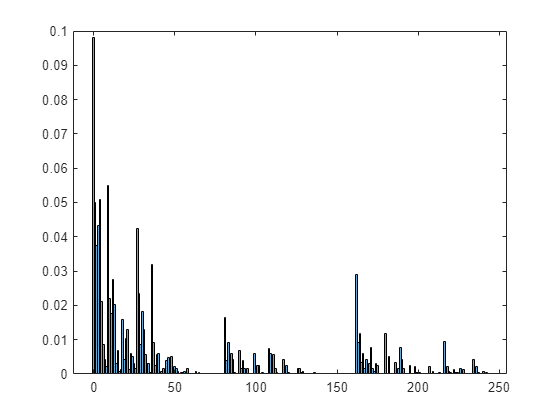


idx = testwords == "STARE";
histogram(D(:,idx),"BinMethod","integers","Normalization","probability")

Rank all guesses to find the best first guess.

% Get the "value" (number of different scores) for each word
numscoreposs = rankwords(D);
% Compile into a table and sort
words = table(testwords,numscoreposs,'VariableNames',["Word","NumScorePossibilities"]);
words = sortrows(words,"NumScorePossibilities","descend");
head(words)

ans = 8×2 table
     Word      NumScorePossibilities
    _______    _____________________
    "TRACE"             150         
    "CRATE"             148         
    "SLATE"             147         
    "PARSE"             146         
    "CRANE"             142         
    "STALE"             142         
    "HEART"             141         
    "LEAST"             140         

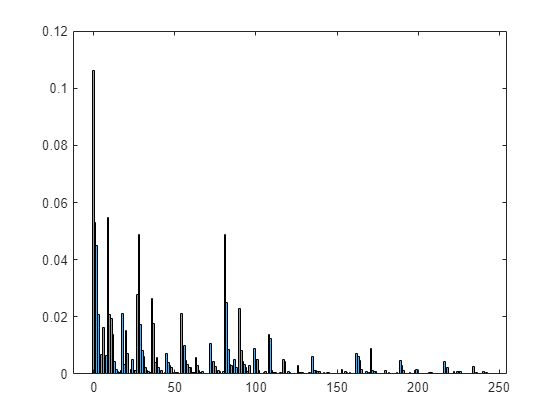


% Look at the distribution of score possibilities
idx = testwords == words.Word(1);
histogram(D(:,idx),"BinMethod","integers","Normalization","probability")

Zoom in to see how this translates into responses

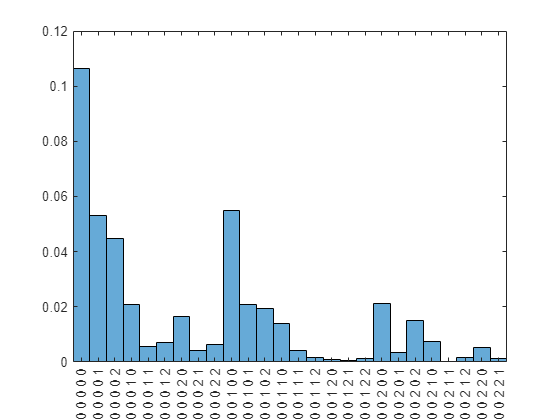

% Zoom in
xticks(0:242)
% Add pretty labels
xticklabels(scores)
xtickangle(90)
xlim([-0.5 25.5])

### Evaluate how well the algorithm performs

Play every possible game

% Preallocate results
num_games = numel(testwords);
wins = NaN(num_games,1);
guesses = strings(num_games,6);
num_guesses = NaN(num_games,1);
scores = NaN(num_games,6);
% Same info is passed into playwordle each game, except which word is the target
playonegame = @(target) playwordle(target,testwords,D,lettercounts,probs);
% Loop over every target word
tic
for k = 1:num_games
    % Play a game with the kth word as the target
    [wins(k),num_guesses(k),guesses(k,:),scores(k,:)] = playonegame(testwords(k));
end
toc

Elapsed time is 121.390600 seconds.


Analyze the results

% Win percentage
fprintf("This strategy results in winning ~%0.1f%% of the time.\n",sum(wins)/numel(wins)*100)

This strategy results in winning ~99.6% of the time.


% Find the number of guesses it takes to win. Extract only winning results,
% find how many words (ie not blanks) have been guessed
num_guesses = sum(guesses(wins==1,:)~="",2);
% Display stats
fprintf("Average number of guesses: %0.2f%.\n",mean(num_guesses))

Average number of guesses: 3.52

fprintf("Median number of guesses: %0.1f%.\n",median(num_guesses))

Median number of guesses: 3.0

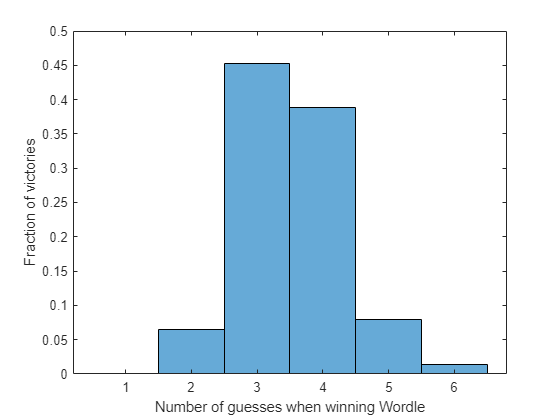

% Make histogram
histogram(num_guesses,"Normalization","probability")
xlabel("Number of guesses when winning Wordle")
ylabel("Fraction of victories")

Analyze the algorithm's strategy

% First guess
firstword = guesses(1,1);
fprintf("First guess: %s.\n",firstword)

First guess: TRACE.


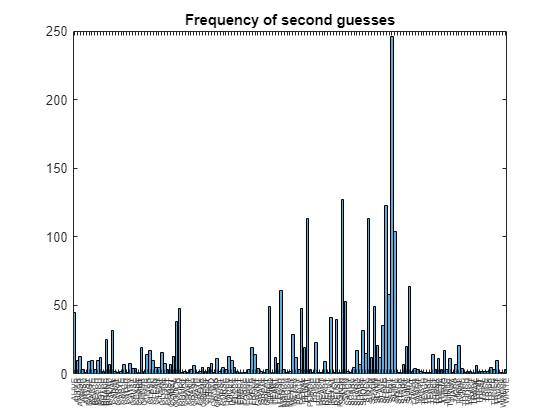

% Second guess (depends on results from first)
histogram(categorical(guesses(:,2)))
title("Frequency of second guesses")
ax = gca;
ax.XAxis.FontSize = 6;

% Make a table of the second guesses, score that lead to them, and frequency of occurrence
% Start with unique guesses and their counts
guess2 = table(guesses(:,2),wins,'VariableNames',["Guess","Wins"]);
guess2 = groupsummary(guess2,"Guess","sum");
guess2.Properties.VariableNames = {'Guess','Count','Wins'};
% Make a table of guesses and scores; join with table of guesses and counts
guess2 = innerjoin(guess2,unique(table(vecdigits(scores(:,1),3,5),guesses(:,2),'VariableNames',["Score","Guess"]),"Rows"));
guess2 = sortrows(guess2,"Count","descend");
% Turn counts into percentages
guess2.Perc = guess2.Count/sum(guess2.Count);
guess2.CumulativePerc = cumsum(guess2.Perc);
% Reorder variables
guess2 = movevars(guess2,"Score","Before",1);
% View top few rows
head(guess2,15)

ans = 15×6 table
            Score             Guess     Count    Wins      Perc      CumulativePerc
    _____________________    _______    _____    ____    ________    ______________
    0    0    0    0    0    "SLIMY"     246     243      0.10626       0.10626    
    0    0    1    0    0    "SALON"     127     127      0.05486       0.16112    
    0    0    0    0    1    "SLEEP"     123     123     0.053132       0.21425    
    1    0    0    0    0    "POINT"     113     113     0.048812       0.26307    
    0    1    0    0    1    "SIREN"     113     111     0.048812       0.31188    
    0    0    0    0    2    "SNIPE"     104     104     0.044924        0.3568    
    0    1    0    0    0    "SURLY"      64      64     0.027646       0.38445    
    0    1    1    0   

Look at the words that caused problems

% Get the words that resulted in a loss
lose = wins == 0;
% Make a nice formatted display of the words and the guesses made
str = sprintf("Target |  Guesses");
str = str + newline + repmat('-',1,55) + newline;
str = str + sprintf("%s  |  "+join(repmat("%s",1,6),"   ")+"\n",[testwords(lose) guesses(lose,:)]');
disp(str)

Target |  Guesses
-------------------------------------------------------
BAKER  |  TRACE   RELAY   GAMER   SAFER   PARER   WAVER
BOXER  |  TRACE   SIREN   REVEL   POWER   HOMER   FOYER
HATCH  |  TRACE   CATCH   BATCH   PATCH   MATCH   LATCH
HILLY  |  TRACE   SLIMY   BILLY   FILLY   DILLY   WILLY
HOLLY  |  TRACE   SLIMY   BULLY   FOLLY   GOLLY   DOLLY
JAUNT  |  TRACE   SATIN   GAUNT   DAUNT   HAUNT   VAUNT
JOKER  |  TRACE   SIREN   REVEL   POWER   HOMER   FOYER
JOLLY  |  TRACE   SLIMY   BULLY   FOLLY   GOLLY   DOLLY
WATCH  |  TRACE   CATCH   BATCH   PATCH   MATCH   LATCH



Look at the list of words with these letter patterns

testwords(endsWith(testwords,"A"+lettersPattern(1)+"ER"))'

ans = 1×29 string array
    "BAKER"    "BALER"    "CAPER"    "CATER"    "EAGER"    "EATER"    "GAMER"    "GAYER"    "GAZER"    "HATER"    "LAGER"    "LATER"    "LAYER"    "MAKER"    "PALER"    "PAPER"    "PARER"    "PAYER"    "RACER"    "RARER"    "SAFER"    "SANER"    "TAKER"    "TAMER"    "TAPER"    "WAFER"    "WAGER"    "WATER"    "WAVER"

testwords(endsWith(testwords,"O"+lettersPattern(1)+"ER"))'

ans = 1×25 string array
    "BOXER"    "CORER"    "COVER"    "COWER"    "FOYER"    "GONER"    "HOMER"    "HOVER"    "JOKER"    "LOSER"    "LOVER"    "LOWER"    "MOVER"    "MOWER"    "POKER"    "POSER"    "POWER"    "ROGER"    "ROVER"    "ROWER"    "SOBER"    "SOWER"    "TOWER"    "VOTER"    "WOOER"

testwords(endsWith(testwords,"ATCH"))'

ans = 1×7 string array
    "BATCH"    "CATCH"    "HATCH"    "LATCH"    "MATCH"    "PATCH"    "WATCH"

testwords(endsWith(testwords,"ILLY"))'

ans = 1×6 string array
    "BILLY"    "DILLY"    "FILLY"    "HILLY"    "SILLY"    "WILLY"

testwords(endsWith(testwords,"OLLY"))'

ans = 1×5 string array
    "DOLLY"    "FOLLY"    "GOLLY"    "HOLLY"    "JOLLY"

testwords(endsWith(testwords,"AUNT"))'

ans = 1×6 string array
    "DAUNT"    "GAUNT"    "HAUNT"    "JAUNT"    "TAUNT"    "VAUNT"

Investigate why some of these are hard

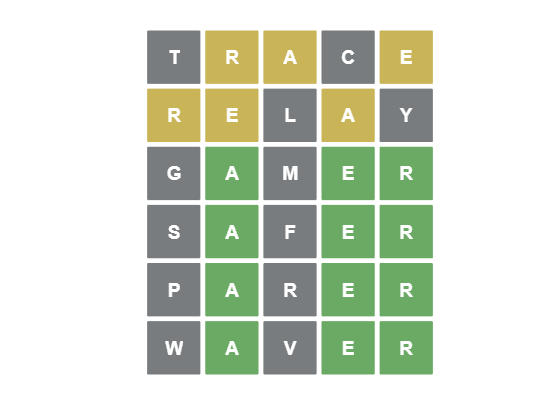

idx = testwords == "BAKER";
figure
drawwordle(guesses(idx,:),vecdigits(scores(idx,:),3,5))

testwords(endsWith(testwords,"A"+lettersPattern(1)+"ER") & ~contains(testwords,["T","C","L","Y"]))'

ans = 1×13 string array
    "BAKER"    "EAGER"    "GAMER"    "GAZER"    "MAKER"    "PAPER"    "PARER"    "RARER"    "SAFER"    "SANER"    "WAFER"    "WAGER"    "WAVER"

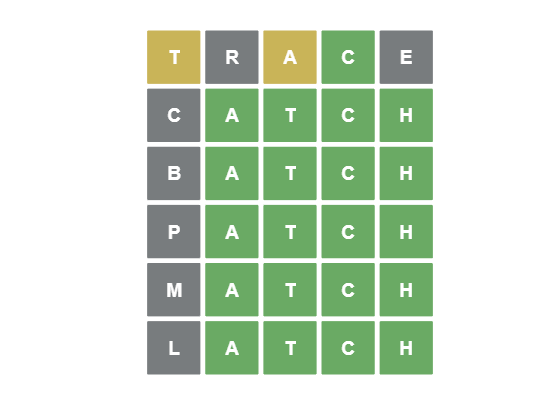


idx = testwords == "WATCH";
drawwordle(guesses(idx,:),vecdigits(scores(idx,:),3,5))

Visualize best opening gambits

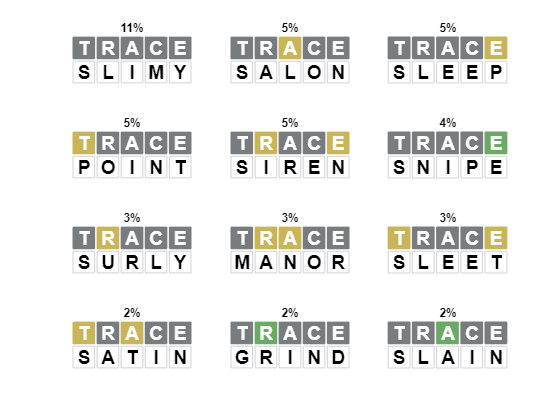

tiledlayout(4,3)
for j = 1:12
    nexttile
    drawwordle([firstword;guess2.Guess(j)],[guess2.Score(j,:);-1*ones(1,5)])
    title(round(100*guess2.Perc(j))+"%")
end

Visualize the entire set of opening pairs

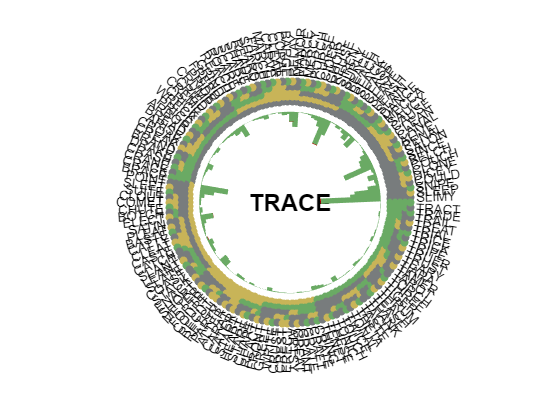

figure
wordwheel(guess2)

Helper functions

function txt = stringscore(s)
% Turn numeric score (0:243) into 5-element vector of digits (0:2),
% then into pretty text
txt = join(string(vecdigits(s(:),3,5)));
end

function lprob = letterdistribution(words)
% split our words into their individual letters
letters = split(words,"");
% this also creates leading and trailing blank strings, drop them
letters = letters(:,2:end-1);

% Calculate the distribution of letters in each word position
AZ = string(char((65:90)'));
lcount = zeros(26,5);
for k = 1:5
    lcount(:,k) = histcounts(categorical(letters(:,k),AZ));
end
lprob = lcount./sum(lcount);  % Normalize
end